# Testing the PGA algorithm on dots

addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab_algorithm_real_data\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab_algorithm_real_data\addition\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab_algorithm_real_data\functions\')
addpath('C:\MatkivskiyV\science\article8\ab_comp_matlab_algorithm_real_data\HelpFun\','-end')

**Set the constances and generate polinomials**

N = 512;
Global_constants = zeros(10,1);
lam = 0.85*10^-3; Global_constants(1)=lam; %Длина волны
k = 2*pi/(lam); Global_constants(2)=k; % Wave number in invers millimeters
dx = 300/256*10^-3; Global_constants(4)=dx; % it is pixel size in mm
L = dx*N; Global_constants(5)=L; % Length of image area

[x,y] = meshgrid(-L/2:dx:L/2-dx);
x = x + dx/2 ; % Это нужно, чтобы отцентрировать is_in_circle
y = y + dx/2;

radius = 0.14;
% This radius is determinated empirically. noise_area is area over which
% the noise is calculated
is_in_circle = circ(sqrt(x.^2+y.^2)/radius);
noise_area = circ(sqrt(x.^2+y.^2)/0.11) & ~circ(sqrt(x.^2+y.^2)/0.09);

Global_constants(10) = radius;
Global_constants(6) = 257; %xc
Global_constants(7) = 257; %yc

% tempz is used for sub-images that should not intersect with image borders
tempz = true(N,N);
clear Sh0;

fieldsprep; %This file contains references on different data with comments


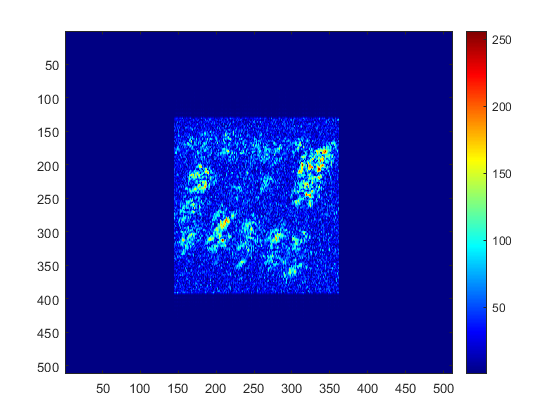

figure();
imagesc(abs(Ea)); colormap('jet'); colorbar

Fourier of the image:

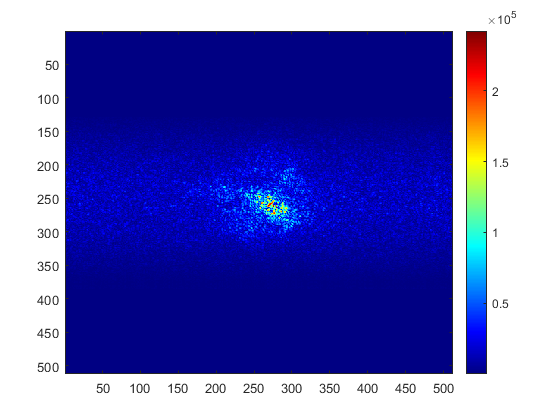

figure();
imagesc(abs(FTS(Ea))); colormap('jet'); colorbar

####  Generating Gausse-Hermite and polynomials

her_R = w is evaluated from the condition: $2^n x^n \exp \left(-\frac{x^2 }{w^2 }\right)=1$, there x = dx2t*64/2

% Generate_HermPol = true; %Calculate Gauss-Hermite polynomials?
% her_N = 6;    % The degree of Herm. pol.
% her_R = 0.057; % The radius of Herm. pol.
% dx2t = dx*N/64;
% if Generate_HermPol == true
%     [x2,y2] = meshgrid(-L/2:dx2t:L/2-dx2t);
%     x2 = x2 + dx2t/2; % Это нужно, чтобы отцентрировать is_in_circle
%     y2 = y2 + dx2t/2;
%     H256 = HermitePol(x,y,her_N,her_R);
%     H64 = HermitePol(x2,y2,her_N,her_R);
% end

## Next we starts compensation algorithm

Q = [16,12,8,4];
N2 = size(Q,2);
Gst = repmat(E*0,[1 1 N2+1]);
Sh0(1) = shann_entropy(E(tempz));
u = fftshift(fft2(fftshift(Ea)));
Ev = Ea;

Deg = 6;

dx2t = dx*N/64;
[x2,y2] = meshgrid(-L/2:dx2t:L/2-dx2t);
x2 = x2 + dx2t/2;
y2 = y2 + dx2t/2;

% [Z,~,~] = zerfit(x,y,x,radius,deg2);
% [Z2,~,is_in_circle2] = zerfit(x2,y2,x2,radius,deg2);

fprintf('Initial image entropy = %g \n',Sh0(1));

Initial image entropy = 12.6862 



noise_area = circ(sqrt(x.^2+y.^2)/0.13) & ~circ(sqrt(x.^2+y.^2)/0.09);

for t2 = 1:1

    fprintf('circle %g \n',t2);
    fprintf('window = %g \n',Q(t2));

    [ATF] = PGA_find4_fft( Ev,Q(t2),tempz,radius,Global_constants,...
                                      8,radius,0, is_in_circle, 1, E);        
%     [ a3 ] = grad_svd( angle(ATF), 64, Z2, is_in_circle2);
    
    [Dc3,Phase] = DeconWienHZ(ATF,E,noise_area,Deg);
    
    if t2 == 1
        u2 = u.*Dc3;
    else 
        u2 = u.*exp(-1j*Phase);
    end
    
  
    u2 = u2*sqrt( sum(abs(u(:)).^2)/sum(abs(u2(:)).^2) );
    Ev = ifftshift( ifft2( ifftshift(u2)  ) );
    u = u2;
    Sh0(t2+1) = shann_entropy(Ev(tempz));

    fprintf('Entropy inside the loop = %g \n',Sh0(t2+1));
end

circle 1 


window = 16 


Количество точек = 60 


Entropy inside the loop = 14.8007 


ATF image.

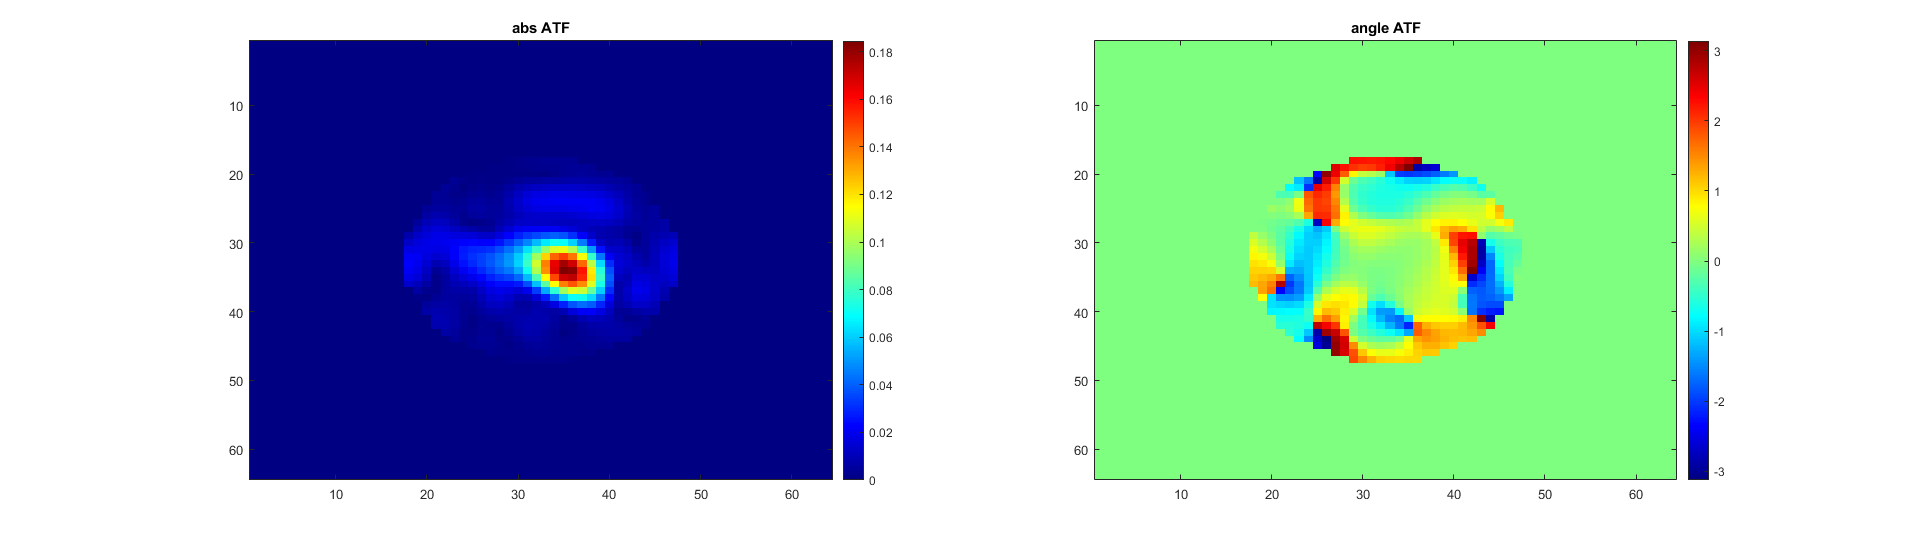

h2 = figure();
subplot(1,2,1);
imagesc(abs(ATF)); colormap(jet); colorbar();
title('abs ATF')
subplot(1,2,2);    
imagesc(angle(ATF)); colormap(jet); colorbar();
title('angle ATF')
set(h2,'Units','normalized','position',[0 0 1 .5])

Decomposition ATF by polynomials/

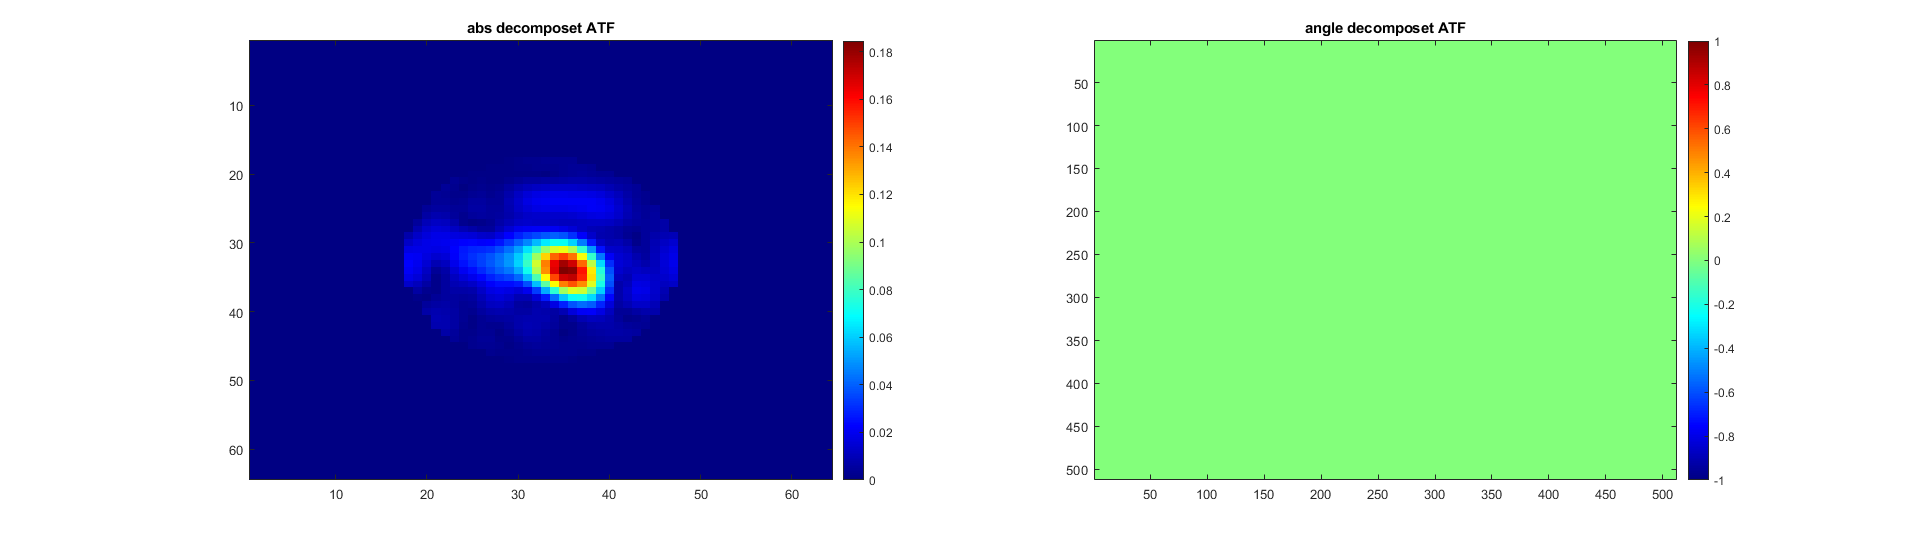

h22 = figure();
subplot(1,2,1);
imagesc(abs(ATF)); colormap(jet); colorbar();
title('abs decomposet ATF')
subplot(1,2,2);    
imagesc((Phase)); colormap(jet); colorbar();
title('angle decomposet ATF')
set(h22,'Units','normalized','position',[0 0 1 .5])

Invers ATF image after decomposition by polinomials. We can see problems with phase.

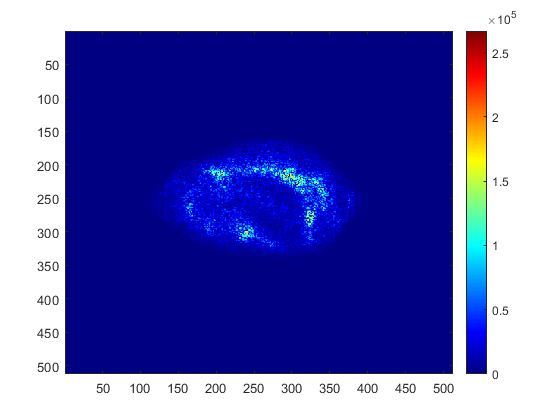

h21 = figure();
subplot(1,2,1);
imagesc(abs(Dc3)); colormap(jet); colorbar();
title('abs Dc')
subplot(1,2,2);    
imagesc(angle(Dc3)); colormap(jet); colorbar();
title('angle Dc')
set(h21,'Units','normalized','position',[0 0 1 .5])
figure();
imagesc(abs(u2)); colormap(jet); colorbar();

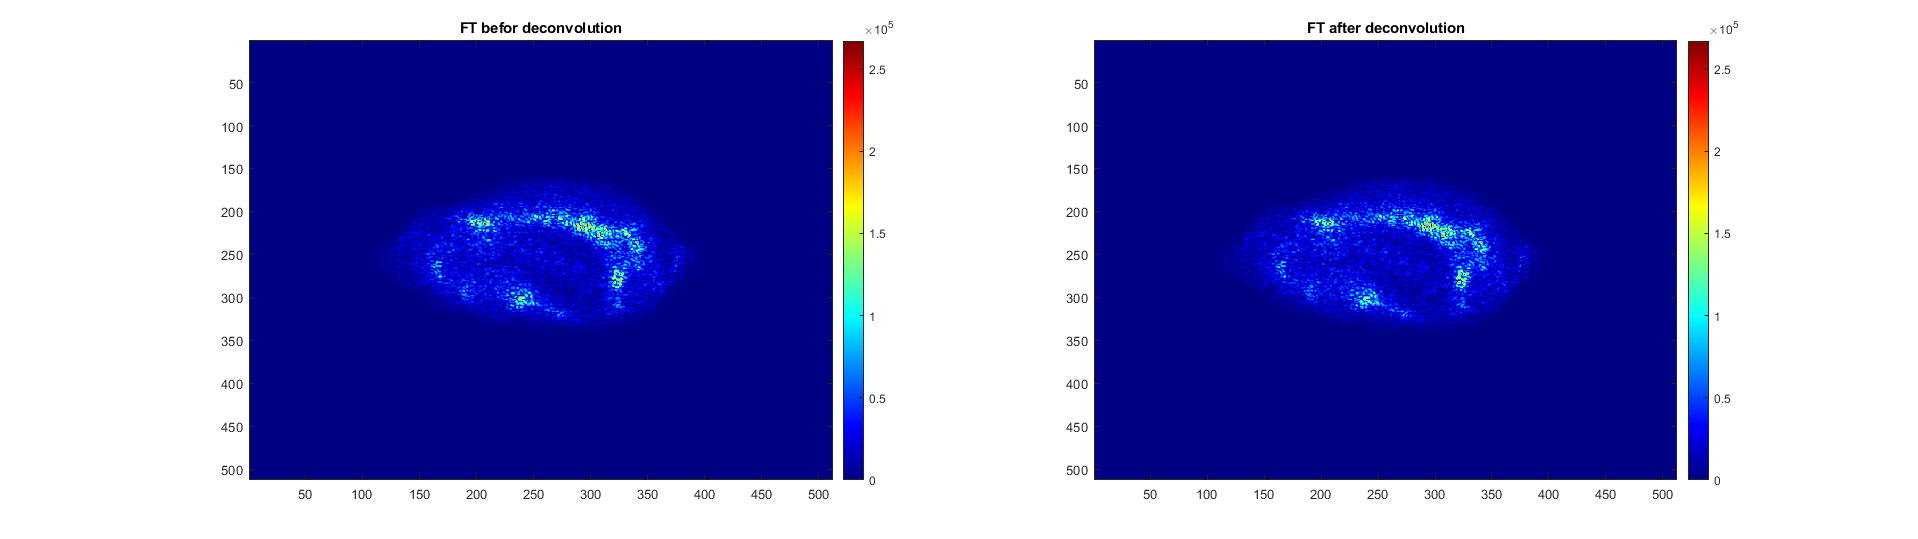

h3 = figure();
subplot(1,2,1);    
imagesc(abs(u)); colormap(jet); colorbar();
title('FT befor deconvolution');
subplot(1,2,2);    
imagesc(abs(u2)); colormap(jet); colorbar();
title('FT after deconvolution')
set(h3,'Units','normalized','position',[0 0 1 .5])

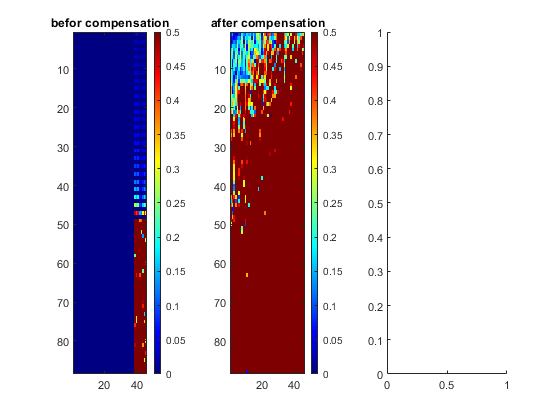

h4 = figure();
subplot(1,3,1);
imagesc(abs(E(103:190,115:160))); colormap(jet); colorbar(); caxis([0 .5]);
title('befor compensation');
subplot(1,3,2);
imagesc(abs(Ev(103:190,115:160))); colormap(jet); colorbar(); caxis([0 .5]);
title('after compensation');
subplot(1,3,3);

imagesc(abs(Eideal(103:190,115:160))); colormap(jet); colorbar(); caxis([0 .5]);

Unrecognized function or variable 'Eideal'.

title('without aberrations');
set(h4,'Units','normalized','position',[0 0 1 .35])
shann_entropy(Ev(103:190,115:160))

**Dots with only phase ore amplitude compensation**

Only amplitude

u2 = u.*abs(Dc3);
u2 = u2*sqrt( sum(abs(u(:)).^2)/sum(abs(u2(:)).^2) );
Ev1 = ifftshift( ifft2( ifftshift(u2)  ) );

Only phase

u2 = u.*exp(1j*angle(Dc3));
Ev2 = ifftshift( ifft2( ifftshift(u2)  ) );

h5 = figure();
subplot(1,2,1);
imagesc(abs(Ev1)); colormap(jet); colorbar();
title('Only amplitude');
subplot(1,2,2);
imagesc(abs(Ev2)); colormap(jet); colorbar();
title('Only phase');
set(h5,'Units','normalized','position',[0 0 1 .5])
